# Rad229 - Lecture 14:  Magnetization Preparation

## lec14_01.m:  Saturation Pulse Animation

This code animates a saturation pulse, saving frames if set up.

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

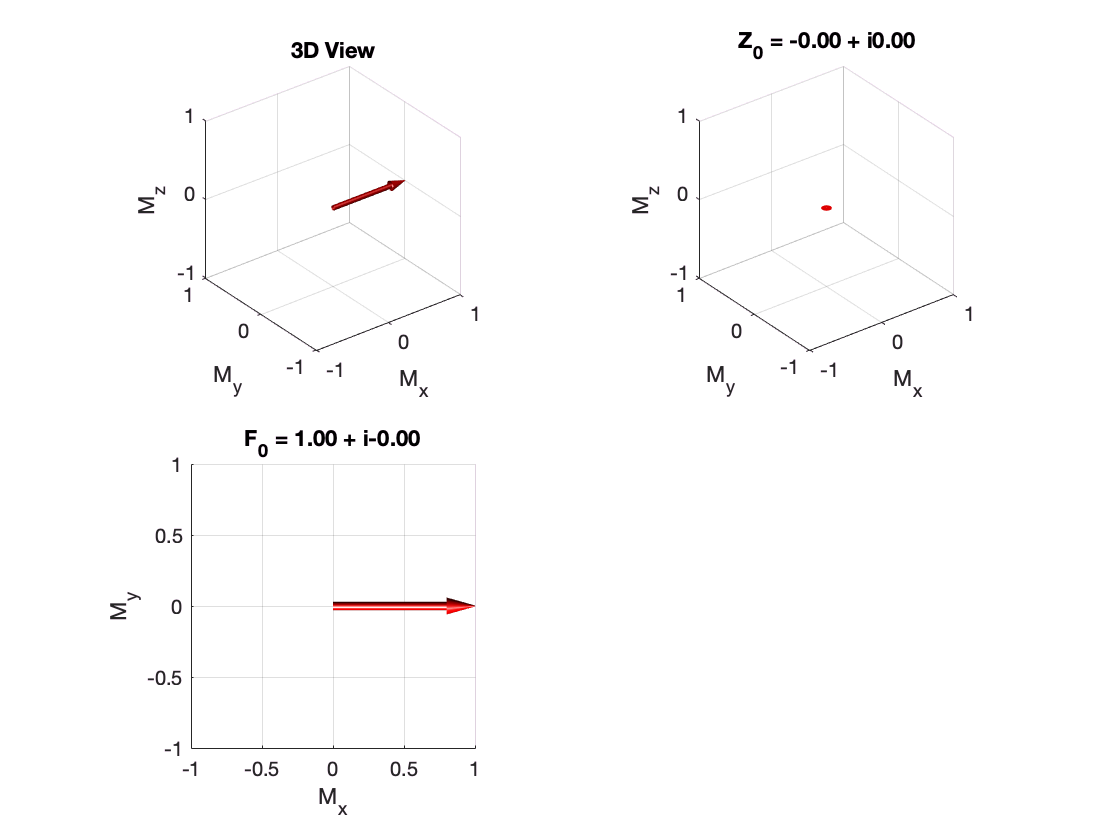

% Lecture 14, Example 01
%
% Animate saturation pulse with recovery.

%global filestem;
%global framenum;
%filestem='/Users/brian/tmp/sat';
%framenum=0;


FZ = epg_m0;

% == Animate RF
Nrf = 24;
for k=0:Nrf 
  epg_showorder(FZ,0);
  if (k<Nrf) FZ = epg_rf(FZ,pi/2/Nrf,pi/2); end;
  subplot(2,2,4); lplot('','',''); title(''); axis off;
  drawnow;
  epg_saveframe;
end;

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

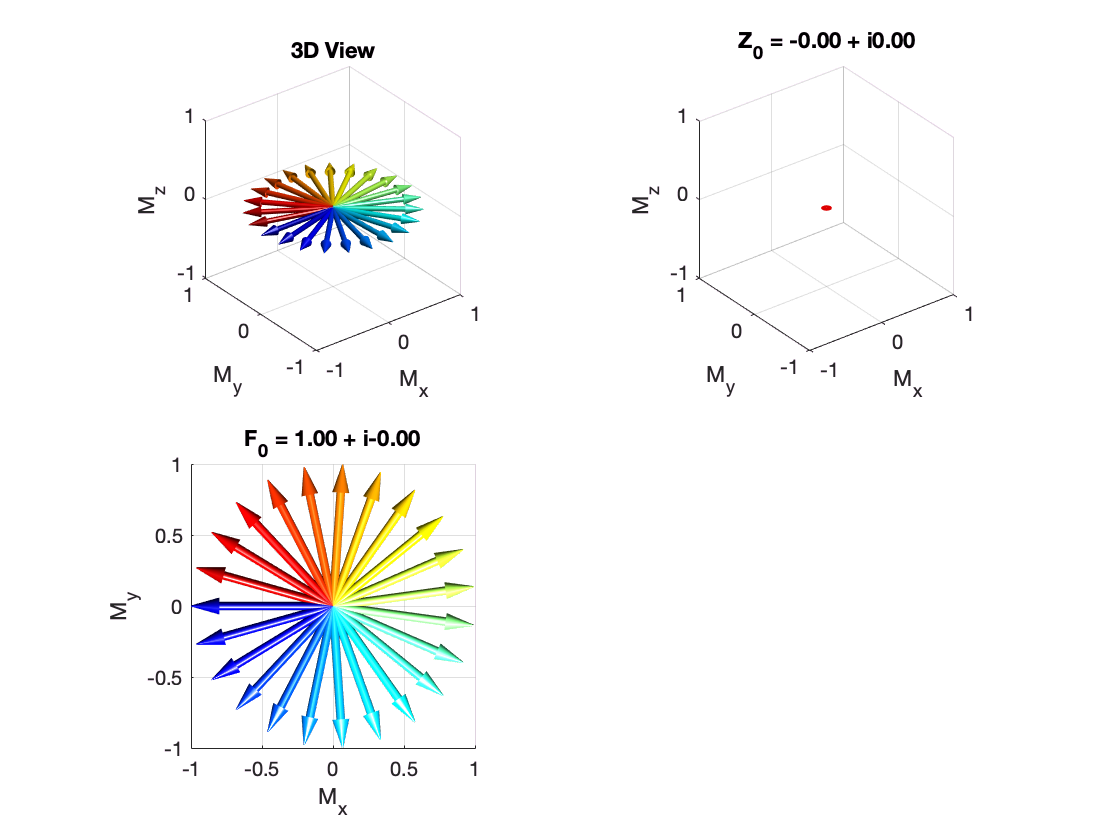


% == Animate Gradient
Ng = 24;
for k=1:Ng
  epg_showorder(FZ,0,k/Ng,23);
  subplot(2,2,4); lplot('','',''); title(''); axis off;
  drawnow;
  epg_saveframe;
end;

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

ftwist = 0

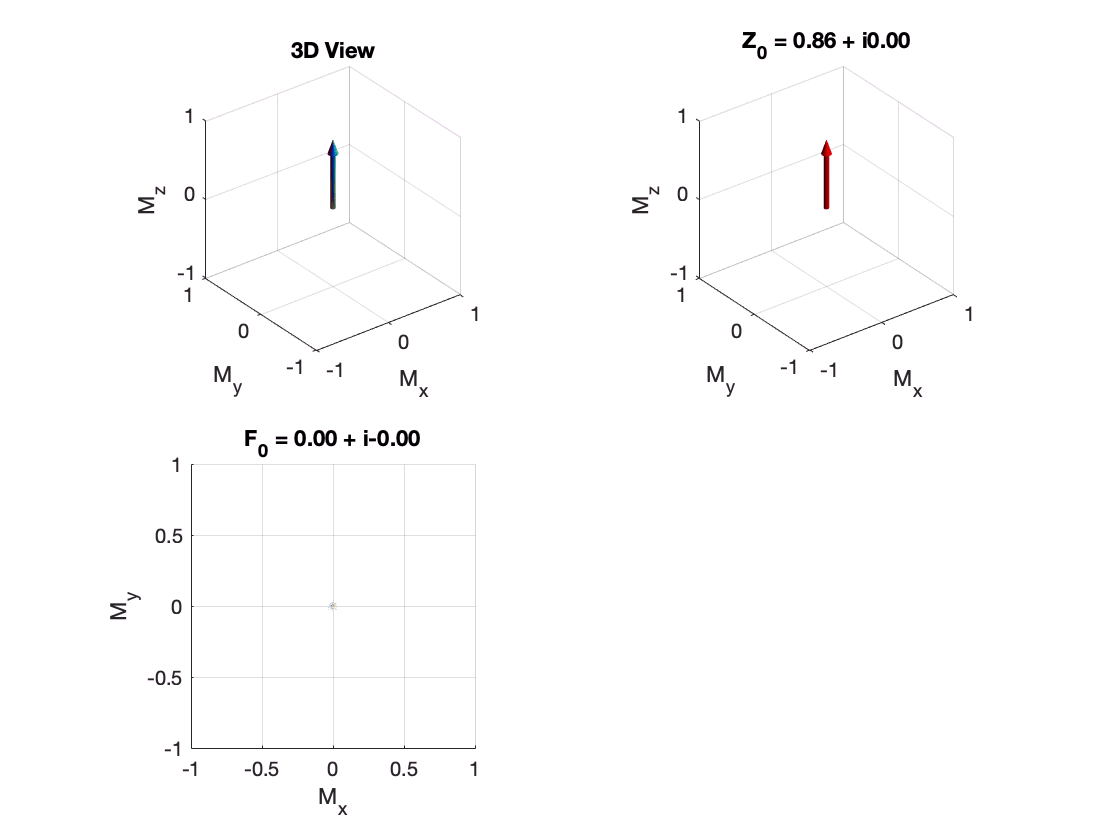


% == Animate Relaxation
Nr = 100;
for k=1:Nr
  FZ = epg_grelax(FZ,300,80,6,0,0,0,1);         % Relaxation
  epg_showorder(FZ,0,1,23);
  subplot(2,2,4); lplot('','',''); title(''); axis off;
  drawnow;
  epg_saveframe;
end;

## lec14_02.m:  Inversion Pulse Animation

This code animates an inversion pulse, saving frames if set up.

% Lecture 14, Example 02
%
% Animate inversion pulse with recovery.  (Include dephaser)

%global filestem;
%global framenum;
%filestem='/Users/brian/tmp/inv';
%framenum=0;


FZ = epg_m0;

% == Animate RF
Nrf = 24;
for k=0:Nrf 
  epg_showorder(FZ,0);
  if (k<Nrf) FZ = epg_rf(FZ,pi/Nrf,pi/2); end;
  subplot(2,2,4); lplot('','',''); title(''); axis off;
  drawnow;
  epg_saveframe;
end;

% == Animate Gradient
Ng = 24;
for k=1:Ng
  epg_showorder(FZ,0,k/Ng,23);
  subplot(2,2,4); lplot('','',''); title(''); axis off;
  drawnow;
  epg_saveframe;
end;

% == Animate Relaxation
Nr = 100;
for k=1:Nr
  FZ = epg_grelax(FZ,300,80,6,0,0,0,1);         % Relaxation
  epg_showorder(FZ,0,1,23);
  subplot(2,2,4); lplot('','',''); title(''); axis off;
  drawnow;
  epg_saveframe;
end;


## lec14_03.m:  Multiple Inversion-Recovery

Here we plot the T1 recovery curves with multiple inversion pulses, over time.

% Lecture 14, Example 03
%
% Show M curves for different T1s, with inversion-recovery.

set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width

T1 = [100 300 500 1000 1500 2000];
m = ones(size(T1));                     % Note we only care about Mz!
invtimes = [0.5, 1000];         % Times where inversions played
t = [0:5000];                           % Time-course in ms

E1 = exp(-(t(2)-t(1))./T1);


for tt = 1:length(t)-1
  f = find(invtimes>=t(tt) & invtimes<t(tt+1));
  if (length(f)>0)
    txt=sprintf('Inversion at time %d',t(tt)); disp(txt);
    m(tt+1,:) = -m(tt,:).*E1+(1-E1);    % Inversion
  else
    m(tt+1,:) = m(tt,:).*E1+(1-E1);     % No Inversion
  end;
end;

plot(t,m);
legend('100ms','300ms','500ms','1000ms','1500ms','2000ms');
lplot('Time (ms)','Signal','Signal vs Time for Multiple Inversion');
hold on;
plot(t,zeros(size(t)),'k-');    % add line along 0
hold off;

Exercise:  Try to choose 2 inversion times to simultaneously null the longest and shortest T1